# Solutions to Exercises on Constrained Polynomial Approximation (2D) (17.12.2024): Part II

Course: Data Science for Engineers II

Author: Dimitar Ninevski

Date: 30.12.2024

## Prepare workspace

close all;
clear;

## Question 1

### Part e.

I decided to write this in a separate live script for clarity. A lot of the code will be copied from the first part.

We have to load throwse dataset.

allData = readmatrix('T3v0_D.csv');

From before we know that the second row can be used as a baseline, whereas the 2508 row was the one we analyzed before.

baseLine = allData(2,:);

We can look at 200 rows around the 2508 one (roughly). So we can go from 2400 till 2600. But we can also define this in a way, that it can be changed easily.

%rows = 1600:5:2600;
rows = 2400:2600;

We can now create a for loop to do the computations, but first let's compute the basis matrices (since they don't change throughout the loop).

#### Define all variables and matrices that don't change in the loop

nrSensorHor = 5;
nrSensorVer = 6;
degX = 2*(nrSensorHor-1);
degY = 2*(nrSensorVer-1);
x = linspace(-1, 1, degX + 1);
y = linspace(-1, 1, degY + 1);

Now we can define the Vandermonde matrices

Vx = vander(x);
Vy = vander(y);

Let's also define the constraint matrices.

Here we will define the constraints a bit differently, just to see how it affects the results. Namely, we want the first and last row to be zero with zero derivative.

vCx = Vx;
vCy = Vy([1 end], :);

Next, let's define the derivatives of the Vandermonde matrices.

Dx = diag(degX:-1:1, -1);
Dy = diag(degY:-1:1, -1);
dVx = Vx*Dx;
dVy = Vy*Dy;

Now, we can also define the derivative constraint matrices.

dCx = dVx;
dCy = dVy([1 end], :);

Finally, we have.

Cx = [vCx; dCx];
Cy = [vCy; dCy];
kronP = kron(Cx, Cy);
N = null(kronP);

While we are at it, we might as well define the plotting basis matrices also.

factor = 20;
xPlot = linspace(-1, 1, factor*nrSensorHor);
yPlot = linspace(-1, 1, factor*nrSensorVer);
Vxb = vander(xPlot);
Vyb = vander(yPlot);
VxPlot = Vxb(:, end-degX:end);
VyPlot = Vyb(:, end-degY:end);

#### Define a placeholder for the results

We will define a 3 dimensional array (sometimes called a tensor), to store all the matrices we compute.

results = zeros(length(yPlot), length(xPlot), length(rows));

#### The for loop

for i = 1:length(rows)

First we extract the row data and normalize it.

    rowNr = rows(i);
    currentData = allData(rowNr, :) - baseLine;
    currentData = currentData./max(currentData);

Next we convert the row into a matrix.

    sensorData = reshape(currentData, nrSensorVer, nrSensorHor);

Now we add the middle points to the data. I will just copy the code from the other script without the comments.

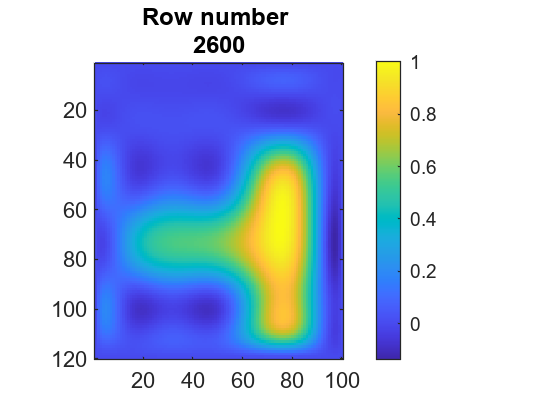

    middlePtsX = (sensorData(:,1:end-1) + sensorData(:,2:end))/2;
    middlePtsY = (sensorData(1:end-1,:) + sensorData(2:end,:))/2;
    newLengthX = size(sensorData, 2) + size(middlePtsX, 2);
    newLengthY = size(sensorData, 1) + size(middlePtsY, 1);
    newData = zeros(newLengthY, newLengthX);
    newData(1:2:newLengthY, 1:2:newLengthX) = sensorData;
    newData(2:2:newLengthY, 1:2:newLengthX) = middlePtsY;
    newData(1:2:newLengthY, 2:2:newLengthX) = middlePtsX;
    middleOfMiddle = (middlePtsX(1:end-1,:) + middlePtsX(2:end,:))/2;
    newData(2:2:newLengthY, 2:2:newLengthX) = middleOfMiddle;

Note that this could also be done via matrix multiplication, since it is just piecewise linear interpolation, but we will not make it more complicated at the moment.

Now we can finally perform the constrained surface fitting. First we compute the coefficients.

    vecCoeffsDer = N*pinv(kron(Vx, Vy)*N)*newData(:);

Next we convert the vector into a matrix.

    valConCoeffs = reshape(vecCoeffsDer, degY + 1, degX + 1);

Finally we compute the surface.

    results(:,:,i) = VyPlot*valConCoeffs*VxPlot';
end

### Create the video

The results are stored in the 3D array called "results". There are different ways to create a video in MATLAB. I have found the following.

First, we define the video name

videoName = ['VideoRows',num2str(rows(1)),'-'...
    ,num2str(rows(end)), '.avi'];

Next, we use the function VideoWriter to "write" to tell MATLAB to create a video.

v = VideoWriter(videoName,"Uncompressed AVI");

The next step, is to open the video, so we can write in it.

open(v)

Finally, we can go through the results and create the video. 

for i = 1:length(rows)

We define the surface we want to work with and create the figure.

    A = results(:,:,i);
    imagesc(A)
    axis image;
    colorbar;
    title(["Row number ", num2str(rows(i))])

Next, we get the frame we want from the figure, using the get frame function. Finally, we write that frame to the video.

    frame = getframe(gcf);
    writeVideo(v,frame)
end

Finally, we need to close the video.

close(v)

From the video, we can see how the values of the sensors change over time. In the 200 rows I have selected, there isn't much change happening, so if we want to see more change, we can select a different range of rows. Alternatively we can take each 10th row (for example) and create video from that. The only thing that needs to change to accomodate for this, is line 5 of the code.